# EXERCISE #5 Model Multi-Link Operation (MLO) in 802.11be

Copyright 2024-2025 The MathWorks, Inc

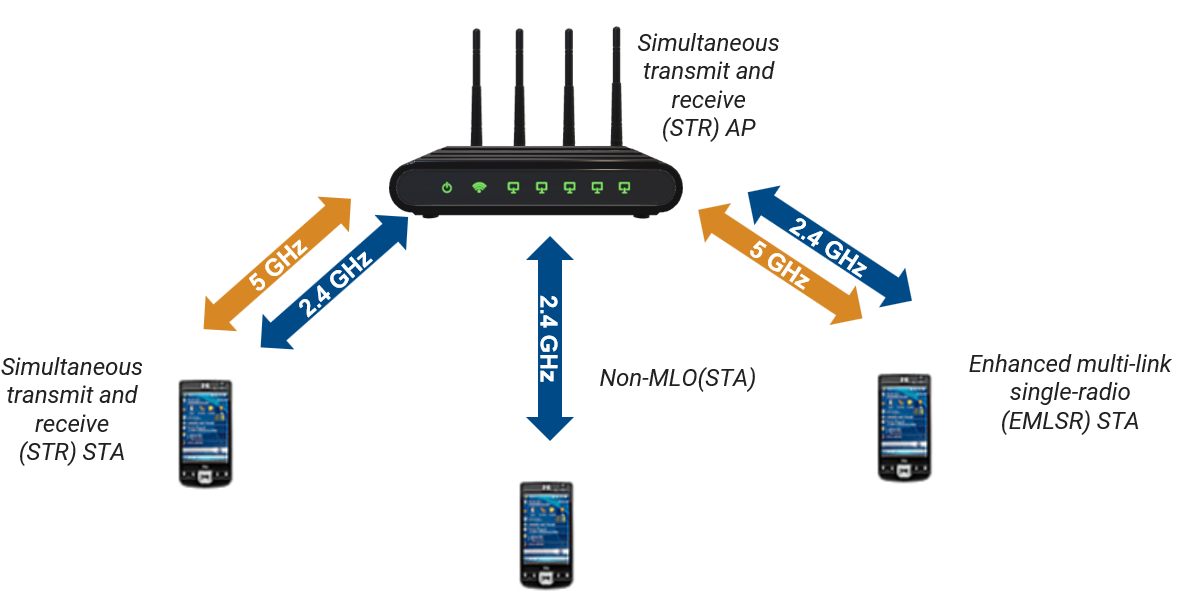

WLAN Network with one STR AP, STR STA, EMLSR STA, and Non MLO STA 

Compare Throughput of Various Multi-Link Operations(MLO) modes and Non-MLO mode

Copyright 2024-2025 The MathWorks, Inc

clear;
format default;
% Set seed of random number generator for reproducible results
rng(1,"combRecursive");
p = addpath(fullfile('.', 'Shared', 'Helpers'), fullfile('.', 'Shared', 'Utilities')); % Add path to helpers and utilities
all_figs = findall(0, 'type', 'figure');close(all_figs); % close all previous windows 

% Set simulation time as 1 Sec
simulationTime = 1;
% Create wireless network simulator
networkSimulator = wirelessNetworkSimulator.init;

%Define positions of nodes
AP_pos  = [0,0,0];
STR_STA_pos = [10,0,0];
EMLSR_STA_pos = [0,10,0];
NON_MLO_STA_pos = [0,0,10];

% Band and channel values for each link
bandAndChannel = [2.4 1;5 36];

Create the AP MLD node, STR STA MLD node, EMLSR STA MLD node

#### Create an STR AP

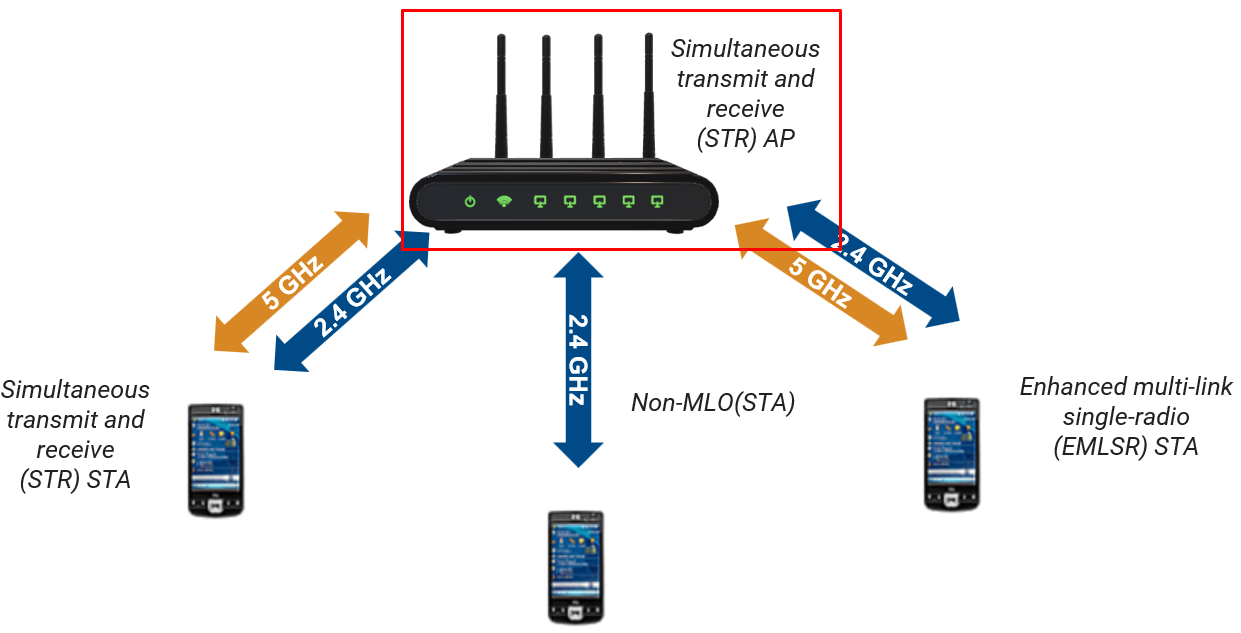

apLinkCfg = wlanLinkConfig("BandAndChannel",bandAndChannel,...
    "NumTransmitAntennas", 2, ...
    "NumSpaceTimeStreams", 2, ...
    "MCS",3);

apMLDCfg = wlanMultilinkDeviceConfig("Mode","AP", ...
    "LinkConfig",apLinkCfg);

apNode = wlanNode("Position",AP_pos, ...
    "Name","AP", ...
    "DeviceConfig",apMLDCfg);

#### Create an STR STA

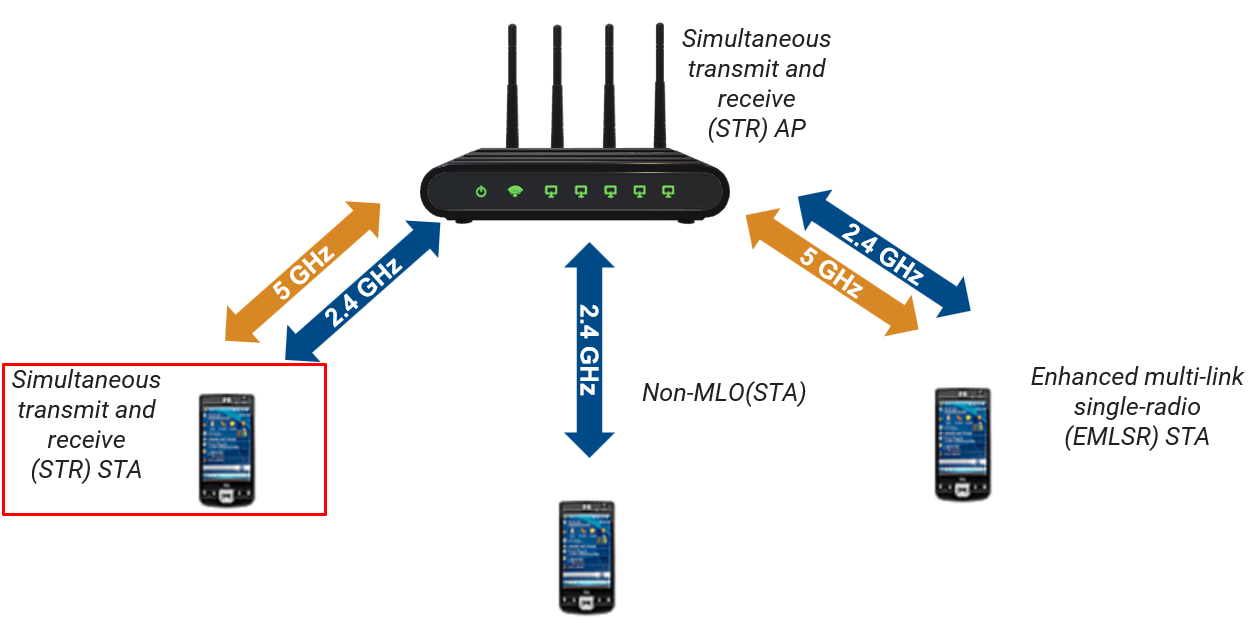


staSTRLinkCfg = wlanLinkConfig("BandAndChannel",bandAndChannel,...
    "NumTransmitAntennas", 2, ...
    "NumSpaceTimeStreams", 2, ...
    "MCS",3);

staSTRMLDCfg = wlanMultilinkDeviceConfig("Mode","STA", ...
    "LinkConfig",staSTRLinkCfg);

staNodes(1) = wlanNode("Position",STR_STA_pos, ...
    "Name","STR STA", ...
    "DeviceConfig",staSTRMLDCfg);

# Task #1/3 Create an link configuration of EMLSR STA 

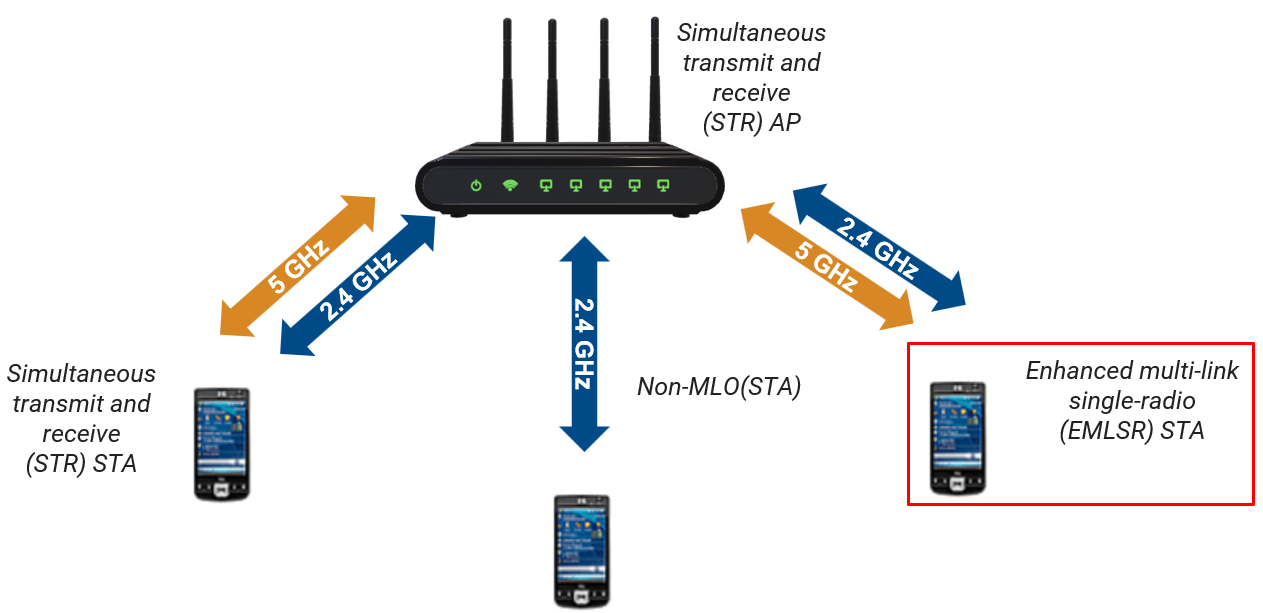

% Create an EMLSR STA 
% Use wlanLinkConfig() function to configure EMLSR STA link
% Write EMLSR STA link configuration in a variable named "STA_EMLSR_Link_cfg"
% Hint: Type "doc wlanLinkConfig" in the MATLAB Command Window, and see the "Syntax" section.
% "BandAndChannel",bandAndChannel
% "NumTransmitAntennas",1
% "NumSpaceTimeStreams",1
% "MCS",3

% Write code here
STA_EMLSR_Link_cfg = wlanLinkConfig("BandAndChannel",bandAndChannel, ...
    "NumTransmitAntennas",1, ...
    "NumSpaceTimeStreams",1, ...
    "MCS",3);

# Task #2/3 Create an device configuration of EMLSR STA

% Use wlanMultilinkDeviceConfig() function to Configure EMLSR STA 
% Write STR STA device configuration in a variable named "STA_EMLSR_Dev_cfg"
% Hint: Type "doc wlanMultilinkDeviceConfig" in the MATLAB Command Window, and see the "Syntax" section.
% Note : use the following values to start with
% "Mode","STA"
% "LinkConfig",STA_EMLSR_Link_cfg
% "EnhancedMultilinkMode","EMLSR"

% Write code here
STA_EMLSR_Dev_cfg = wlanMultilinkDeviceConfig("Mode","STA", ...
    "LinkConfig",STA_EMLSR_Link_cfg, ...
    "EnhancedMultilinkMode","EMLSR");


# Task #3/3 Create an EMLSR STA

% Use wlanNode() function to create EMLSR STA 
% Write EMLSR STA node in a variable named "staNodes(2)"
% Note : use the following values to start with
% "Position",EMLSR_STA_pos
% "Name","EMLSR STA"
% "DeviceConfig",STA_EMLSR_Dev_cfg

### [Help on creating WLAN node ](https://www.mathworks.com/help/wlan/ref/wlannode.html)

% Write code here
staNodes(2) = wlanNode("Position",EMLSR_STA_pos, ...
    "Name","EMLSR STA", ...
    "DeviceConfig",STA_EMLSR_Dev_cfg);

#### Create an Non-MLO STA

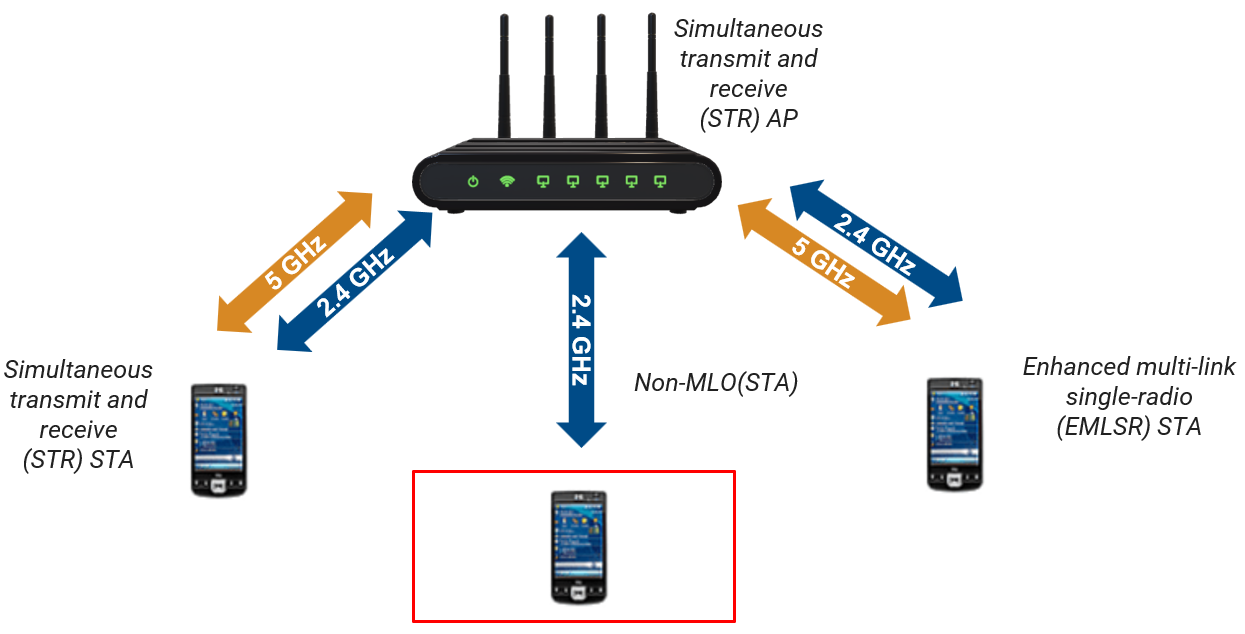


staDeviceConfig = wlanDeviceConfig("Mode","STA","BandAndChannel",bandAndChannel(1,:),...
    "NumTransmitAntennas",1, ...
    "NumSpaceTimeStreams",1, ...
    "MCS",3, ...
    "TransmissionFormat","EHT-SU");

staNodes(3) = wlanNode("Position",NON_MLO_STA_pos, ...
    "Name","Non-MLD STA", ...
    "DeviceConfig",staDeviceConfig);
nodes = [apNode staNodes];

#### Create the Network 

associateStations(apNode,staNodes,FullBufferTraffic="UL");

#### Add the Channel  

- **hSLSTGaxMultiFrequencySystemChannel** is a channel model implemented for WLAN system-level simulations.

- Based on **TGax simulation scenarios** document (doc.: IEEE 802.11-14/0980r16).

- Models **NLOS**, **Model-D delay profile**, and **free-space path loss** as defined in the TGax document.

channel = hSLSTGaxMultiFrequencySystemChannel(nodes);
addChannelModel(networkSimulator,channel.ChannelFcn);

#### Add the network to networkSimulator 

% Add the network to networkSimulator 
addNodes(networkSimulator,nodes);
% Enable packet visualization 
enablePacketVisualization = true;

#### **Enable Visualization**

if enablePacketVisualization
    packetVisObj = hPlotPacketTransitions(nodes,simulationTime,FrequencyPlotFlag=false);
end

#### Create WLAN node performance visualizer

% Create node performance visualization object
perfViewerObj = hPerformanceViewer(nodes,simulationTime);

#### Run the simulation

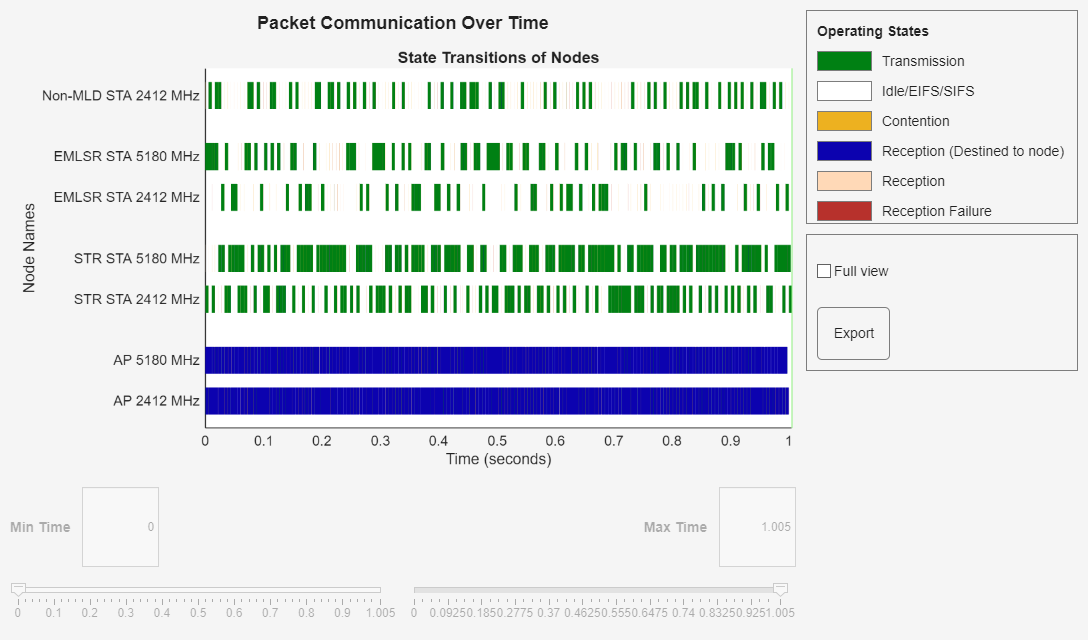

% Run the simulation
run(networkSimulator,simulationTime);

% Calculate throughput at STAs
staThroughputs = throughput(perfViewerObj,[staNodes(:).ID]);
apPacketLossRatio = packetLossRatio(perfViewerObj,[staNodes(:).ID])

apPacketLossRatio =      0     0     0


staAverageReceiveLatency = averageReceiveLatency(perfViewerObj,[staNodes(:).ID])

staAverageReceiveLatency =      0     0     0


#### Plot the STA throughputs as a bar graph

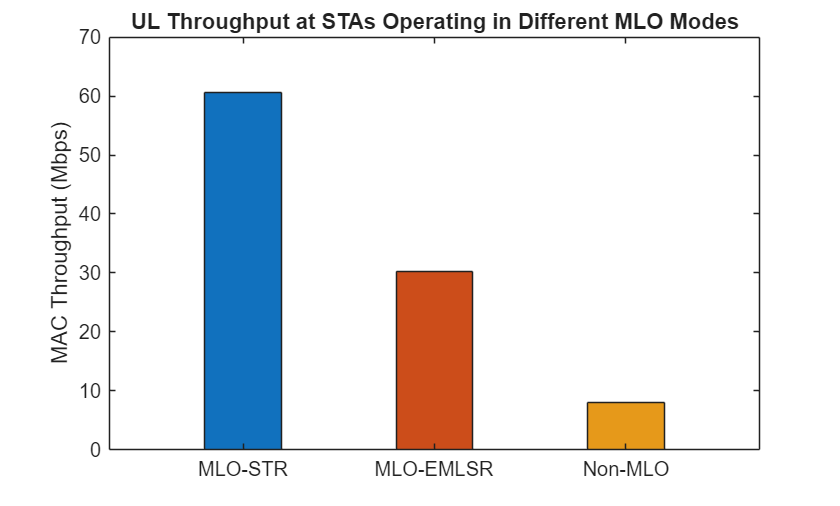

fig = figure;
matlab.graphics.internal.themes.figureUseDesktopTheme(fig);
% Names of the bars
modes = ["MLO-STR" "MLO-EMLSR" "Non-MLO"];
% Plot a bar graph specifying the width of bar (40% of available bar width)
% and face color
b = bar(modes,staThroughputs,0.4,'FaceColor','flat');
% RGB triplets for second and third bars
b.CData(2,:) = [0.8 0.3 0.1];
b.CData(3,:) = [0.9 0.6 0.1];
title("UL Throughput at STAs Operating in Different MLO Modes");
ylabel("MAC Throughput (Mbps)");

stats = statistics(staNodes, "all");
stats(2)

ans = struct with fields:
    Name: "EMLSR STA"
      ID: 3
     App: [1×1 struct]
     MAC: [1×1 struct]
     PHY: [1×1 struct]
    Mesh: [1×1 struct]


stats(2).MAC.Link(1).SuccessfulDataTransmissions

ans = 1025

stats(2).MAC.Link(2).SuccessfulDataTransmissions

ans = 1500

*Copyright 2024 The MathWorks, Inc.*